# Build Detailed House Using Custom Library Components

In this workflow, you will construct a house using custom components. These components leverage the same functionality as the custom components generated in other workflows ([Building Heat Load Estimation,](matlab:open('./BuildingHeatLoadEstimation.mlx')) [Create Building Model with Solar Load](matlab:open('./CreateBuildingModelWithSolarLoad.mlx')), etc). Find custom components listed under `Simscape Custom Components` in the `Simulink Library Browser`. 

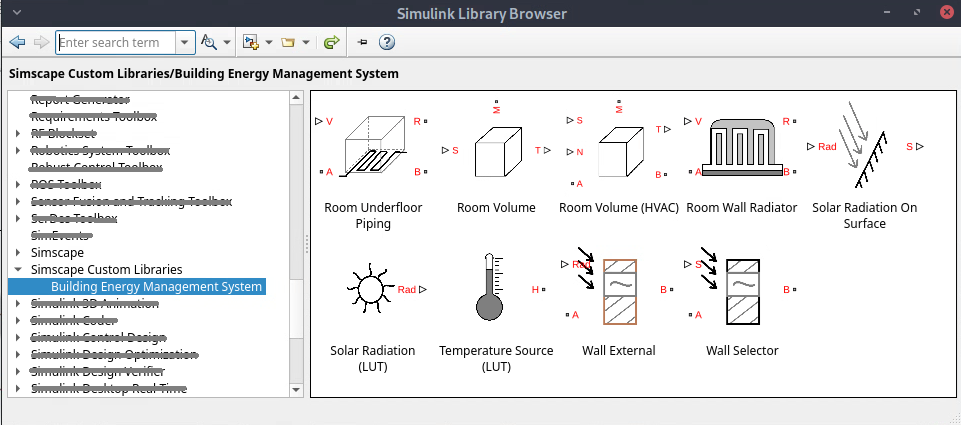

## Build the Model

Use the library elements to build a simple one room house, as described in the picture below. The house is south facing and has one room. The room air volume is divided into smaller control volumes to add more details to the model. In this example, the room air volume is divided into (3,2,2) parts in the (x,y,z) direction. 

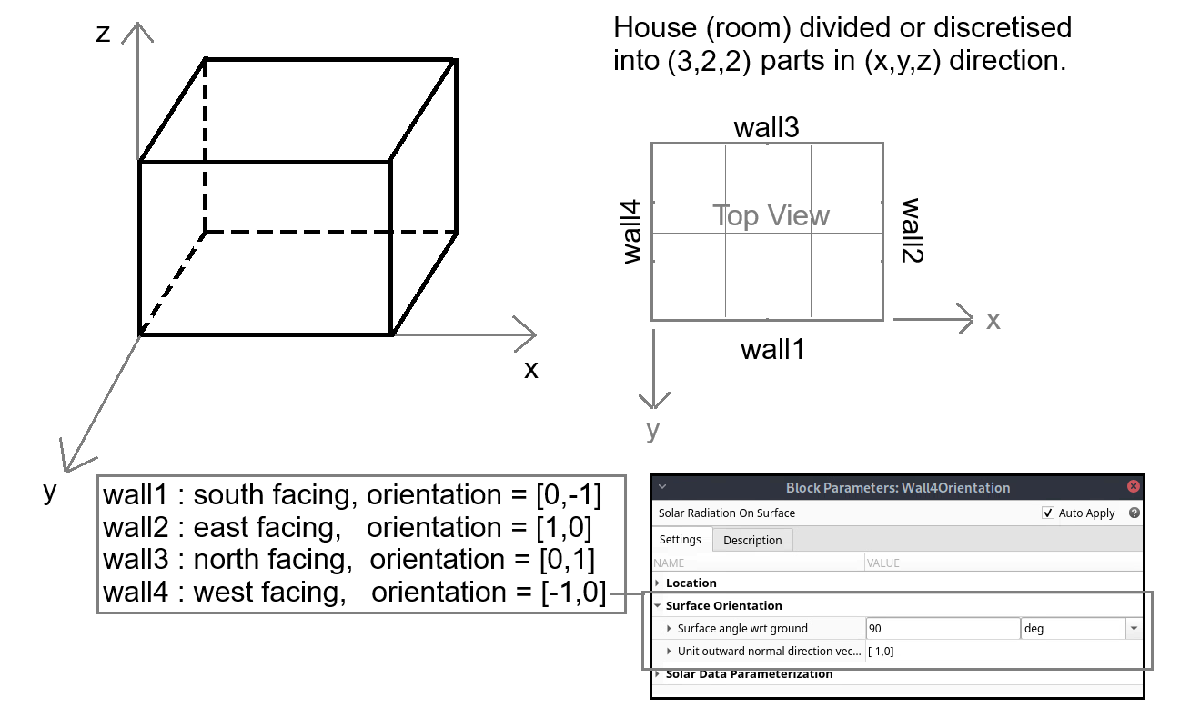

The `Room Volume` library block models these discretized air volumes. The room has four walls, modeled using the `Wall External` block. The wall orientation is specified in the section *Surface Orientation* of the `Wall External` block mask. See [Create Building Model with Solar Load](matlab:open('./CreateBuildingModelWithSolarLoad.mlx')) for convention used for geographical direction: positive x is east, positive y is north, negative y is south, and negative x is west, on a 2D xy plane, as shown in the picture below. So, a south facing vertical wall is specified as having parameters **Unit outward normal direction vector** as [0,-1] and **Surface angle wrt ground** as 90 degrees, in the `Wall External` block mask.

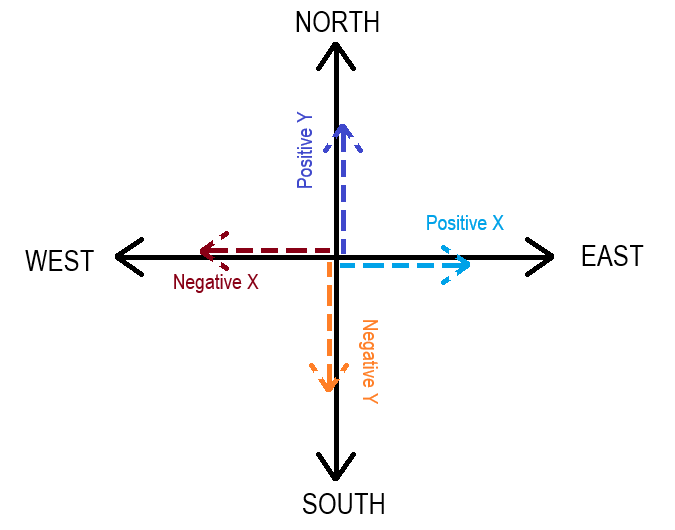

The picture below shows the model implementation in Simscape. The model is externally connected to a solar load. In this workflow, you learn how to evaluate the cooling and/or heating requirements for this house. The `Temperature Source (LUT)` and the `Solar Radiation (LUT)` block specify the ambient conditions.

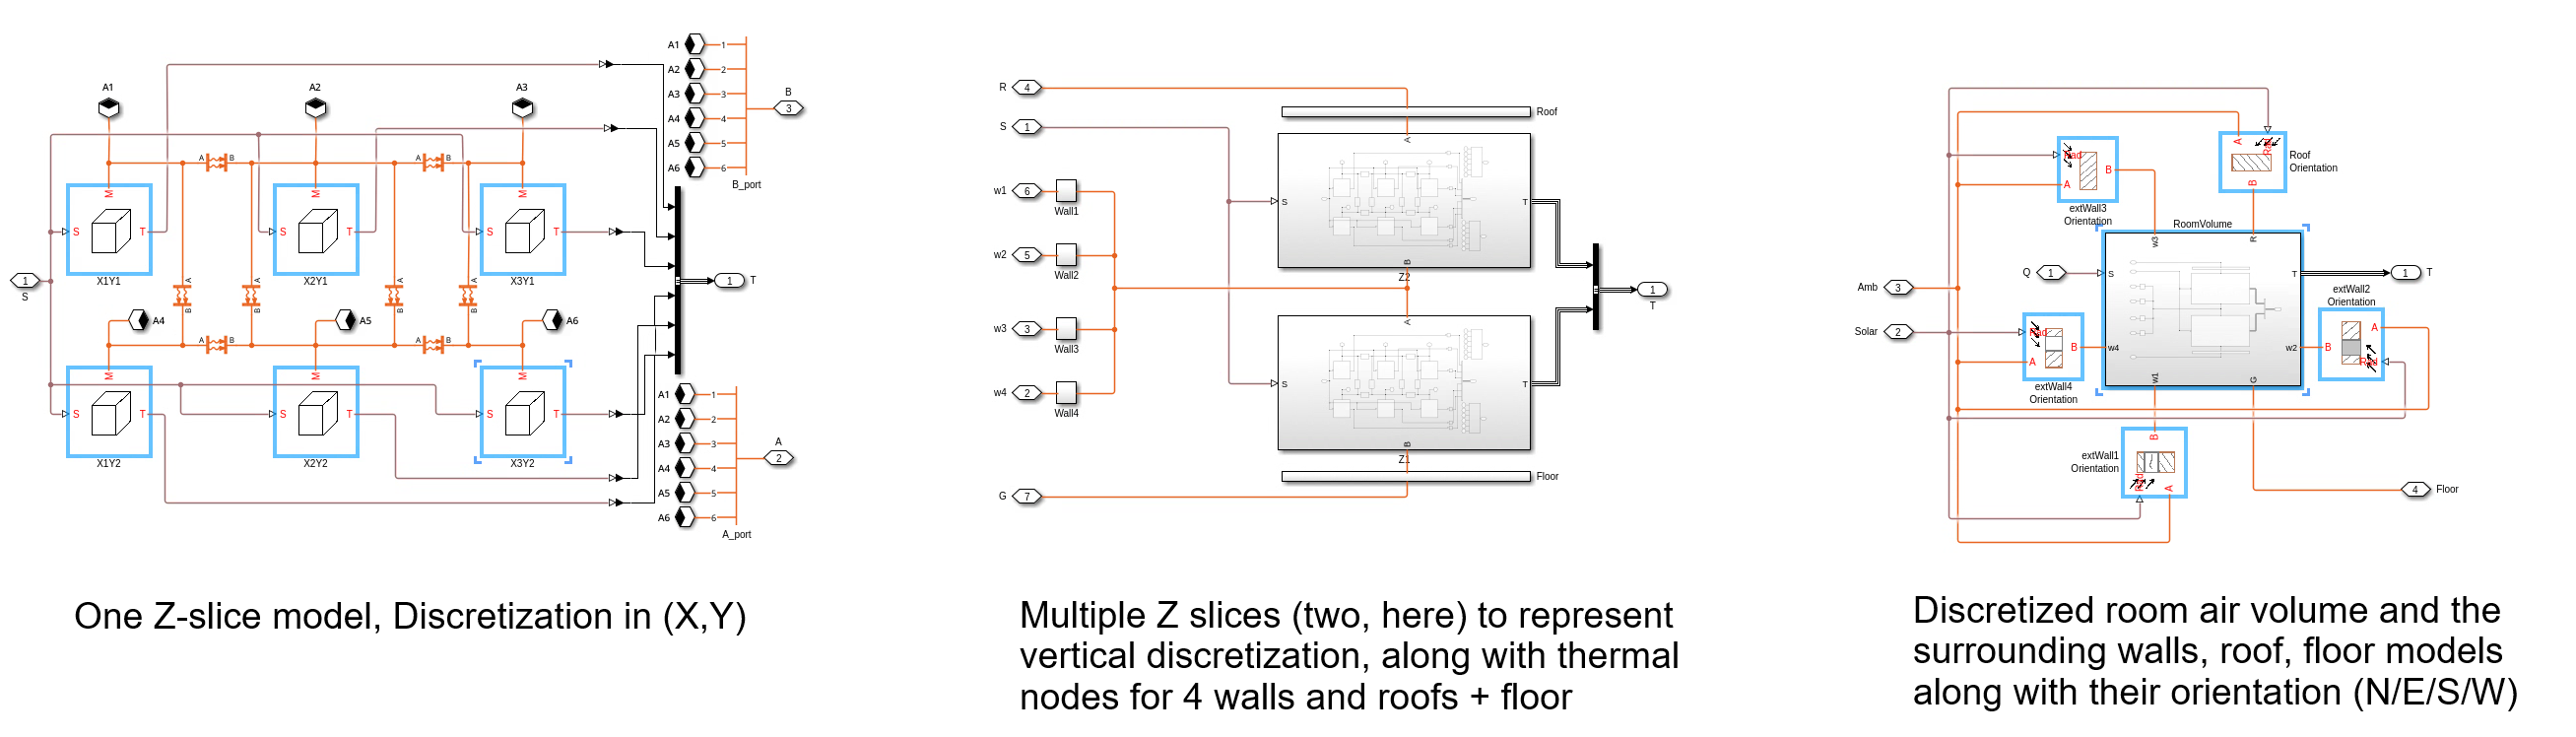

The `Solar Radiation (LUT)` block specifies the solar radiation value on a specified date and time. See how the above model is constructed in the [`DetailedHouse` SLX](matlab:open('./DetailedHouseModel/DetailedHouse.slx')) file.

## Setup Model

Run the `DetailedHouseParameters` livescript and display the the simulation duration in hours.

run("DetailedHouseParameters.mlx");
disp(strcat("Number of hours of simulation ~ ",num2str(house.operational.datetime.numOfHourData),"hrs"))

Number of hours of simulation ~ 720hrs


The workspace variable `house` contains all model parameter data. 

Load the system model and set the room desired temperature as 295K.

load_system("DetailedHouse.slx");
set_param("DetailedHouse/Tset","Value",num2str(295));

The model provides heat to the room (for heating or cooling) based on the difference in the maximum room temperature and the room desired set point temperature, though the port ***S***.

## Run Simulation

Run the model.

simRes = sim("DetailedHouse.slx");

## Calculate HVAC Requirement

Use the house data to calculate and display the HVAC requirement.

simRes.AvgPow = getAveragePower(simRes.DetailedHouseScopeData.extractTimetable);
if simRes.AvgPow > 0
    disp(strcat("Average Cooling Requirement ~ ",num2str(simRes.AvgPow),"W"));
else
    disp(strcat("Average Cooling Requirement ~ ",num2str(abs(simRes.AvgPow)),"W"));
end

Average Cooling Requirement ~ 192.7473W
